# Laboratory exercises: the cart-pendulum system

Riccardo Antonello ([antonello@dei.unipd.it](mailto:antonello@dei.unipd.it)) and Luca Schenato ([schenato@dei.unipd.it](mailto:schenato@dei.unipd.it))

April 15, 2021

Dept. of Information Engineering, University of Padova, Italy

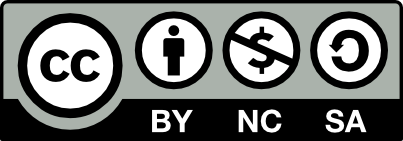

*This work is licensed under a Creative Commons Attribution-NonCommercial-ShareAlike 4.0 International license.*

## Exercise 4: Balance and position control design for the cart-pendulum system using classical methods (root locus method)

This exercise is aimed to illustrate the design of a balance and position controller for the cart-pendulum system shown below, using classical design methods (root locus methods).

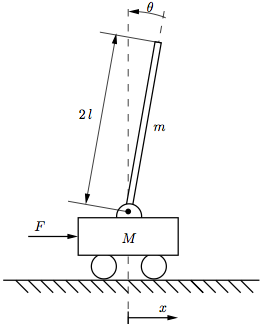

**Figure 1**:  cart-pendulum system.

The nominal values of the system parameters are reported in the table below.

    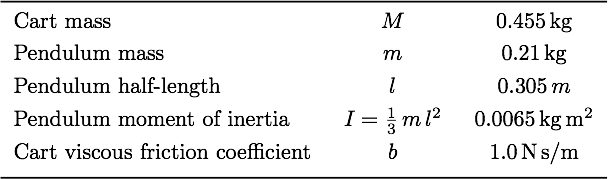

**Table 1**: system parameters.

%   Cart-pendulum parameters
m = 0.21;               %   pendulum mass [kg]
M = 0.455;              %   cart mass [kg]
b = 1.0;                %   cart viscous friction coeff [N/(m/s)]
l = 0.61/2;             %   pendulum half--length [m]
L = 2*l;                %   pendulum length [m]
I = 1/3*m*l^2;          %   pendulum moment of inertia (wrt CoM) [kg*m^2]
g = 9.81;               %   gravity acc [m/s^2]

Ie = I + m*l^2;         %   equivalent inertia at pendulum fulcrum
Me = M + m;             %   total cart+pendlum mass

gam = Me*Ie - (m*l)^2;  %   aux constant

### Design of a balance control loop for the inverted pendulum

Consider the linearized model about an upward equilibrium state obtained in exercise 2, and reported below for convenience:

(1)-(2)     $\Sigma_{u}\;:\;
\left\{\;\;
\begin{array}{l}
I_e\,\ddot{\theta} \,-\, m\,l\,\ddot{x} \,-\, m\,g\,l\,\theta \;=\; 0  \\
-m\,l\,\ddot{\theta} \,+\, M_e\,\ddot{x} \,+\, b\dot{x} \;=\; F	
\end{array}
\right.$

It can be verified that the transfer functions from the input force $F$ to the pendulum swing angle $\theta$ and the cart position $x$ are equal to:

(3)     $P_\theta(s) \,=\, \frac{\Theta(s)}{F(s)} \,=\, \frac{m\,l\,s}{D(s)}\;,\qquad 
P_x(s) \,=\, \frac{X(s)}{F(s)} \,=\, \frac{I_e\,s^2\,-\,m\,g\,l}{s\,D(s)}$

where

(4)     $D(s) \,=\, [M\,m\,l^2\,+\,M_e\,I] s^3 \,+\, b\,I_e\,s^2\,-\,M_e\,m\,g\,l\,s\,-\,b\,m\,g\,l$

The pendulum in the upward vertical position is an unstable system: this can be also verified by noting that the transfer function $P_\theta(s)$ is not BIBO stable.

It is desired to stabilize the inverted pendulum with the closed-loop balance control system shown below:

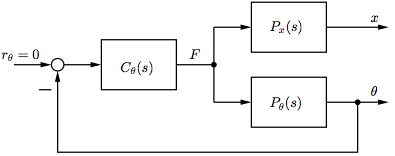

**Figure 2**:  balance control loop for the inverted pendulum.

Since $P_\theta(s)$ is not BIBO stable, it is not possible to design the stabilizing controller $C_\theta(s)$ by applying conventional frequency response methods, such as the *Bode's method *(based on the attainment of a certain phase margin at a desired gain crossover frequency). In fact, such method is suitable only for (minimum-phase) stable plants, or plants with at most few poles at the origin. Therefore, the controller has to be designed by resorting to alternative (and more empirical) methods, such as the *root-locus method*.

1)  Start the design by considering a simple proportional compensator $C_\theta(s) = k$. Verify, by using the (positive) root locus plot, that such compensator is unable to stabilize the closed loop system, for any choice of the positive gain $k>0$.

*Solution*.

The state-space linearized model $(\mathbf{A}_u, \mathbf{B}_u, \mathbf{C}_u, \mathbf{D}_u)$  with state vector $\mathbf{x} = [x,\,\dot{x},\,\theta,\,\dot{\theta}]^T$ about the upward vertical position is:

        
$$\mathbf{A}_u \,=\, \left[
\begin{array}{cccc}
0 & 1 & 0 & 0 \\
0 & -\frac{b\,I_e}{\gamma} & \frac{g (m l)^2}{\gamma} & 0 \\
0 & 0 & 0 & 1 \\
0 & -\frac{b\,m\,l}{\gamma} & \frac{m\,g\,l\,M_e }{\gamma} & 0
\end{array}
\right]\,,

\qquad

\mathbf{B}_u = \left[
\begin{array}{c}
0 \\
\frac{I_e}{\gamma} \\
0 \\
\frac{m l}{\gamma}
\end{array}
\right]\,,

\qquad

\mathbf{C}_u \,=\, \left[
\begin{array}{cccc}
1 & 0 & 0 & 0 \\
0 & 0 & 1 & 0
\end{array}
\right]\,,

\qquad

\mathbf{D}_u \,=\, \left[
\begin{array}{c}
0 \\
0
\end{array}
\right]

$$


where

        $I_e \,=\, I+m\,l^2$,      $M_e \,=\, m + M$,      $\gamma \,=\, M_e\,I_e \,-\, \left( m l \right)^2$

%   state-space model (upward vertical position)
%   - state = [x, dx, th, dth]^T
%   - input = F
%   - output = [x, th]^T
Au = [ ...
    0,  1,  0,  0; ...
    0,  -b*Ie/gam,  g*(m*l)^2/gam,  0; ...
    0,  0,  0,  1; ...
    0,  -b*m*l/gam,  m*g*l*Me/gam,  0  ];

Bu = [ 0;  Ie/gam;  0;  m*l/gam];

Cu = [1, 0, 0, 0; ...
    0, 0, 1, 0];

Du = [0; 0];

sysP = ss(Au, Bu, Cu, Du);

It is possible to verify that the transfer functions from the force input $F$ to the pendulum angular position $\theta$ and the cart position $x$ are equal to:

        $P_\theta(s) \,=\, \frac{\Theta(s)}{F(s)} \,=\, \frac{m\,l\,s}{D(s)}$                   ( *pendulum tf* )

        $P_x(s) \,=\, \frac{X(s)}{F(s)} \,=\, \frac{I_e\,s^2\,-\,m\,g\,l}{s\,D(s)}$          ( *cart tf* )

where

        
$$D(s) \,=\, [M\,m\,l^2\,+\,M_e\,I] s^3 \,+\,
b\,I_e\,s^2\,-\,M_e\,m\,g\,l\,s\,-\,b\,m\,g\,l
$$


%   cart transfer function (in = F, out = x)
sysP = tf(sysP);
sysPx = zpk(sysP(1))     


sysPx =
 
    1.9704 (s+4.912) (s-4.912)
  ------------------------------
  s (s-5.442) (s+5.943) (s+1.47)
 
Continuous-time zero/pole/gain model.




%   pendulum transfer function (in = F, out = th)
sysPth = zpk(sysP(2))    


sysPth =
 
            4.8454 s
  ----------------------------
  (s-5.442) (s+5.943) (s+1.47)
 
Continuous-time zero/pole/gain model.



Consider the (positive) root-locus of the uncompensated pendulum system.

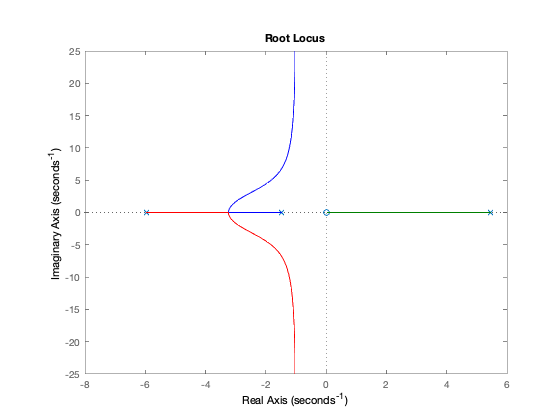

%   root locus of uncompensated sys
figure;
rlocus(sysPth);

For any positive compensator gain, there is always a root locus branch in the open RHP. Therefore, a simple gain is not sufficient to stabilize the closed-loop system.

2)  Modify the compensator by introducing a pole at $s=0$ (integrator), which simplifies with the zero of the plant transfer function $P_\theta(s)$. 

Verify, by using the (positive) root locus plot, that the new compensator $C_\theta(s) = k/s$ is still unable to stabilize the closed-loop system, for any choice of the positive gain $k>0$.

*Solution*.

Consider to add a pole at $s=0$ (i.e. integrator) to the compensator.

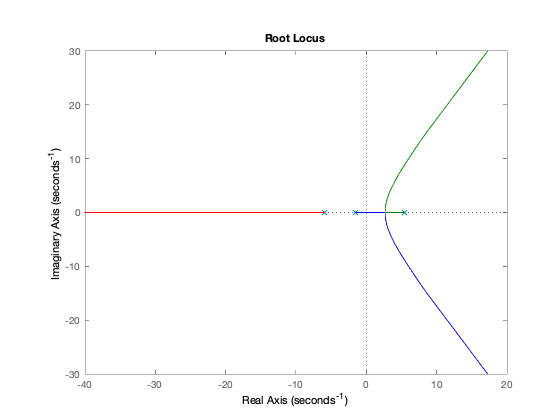

%   add single pole at origin to the compensator
sysCth1 = zpk([], 0, 1);

%   loop tf
sysLth1 = minreal(sysCth1*sysPth);

%   root locus
figure;
rlocus(sysLth1);

The closed-system is still unstable for any choice of the compensator gain. 

It is necessary to bend the two branches in the RHP toward the LHP. This is achieved by adding a zero in the LHP to the compensator ("*attracting*" property of the zeros).

3)  The root locus plotted in point 2 has two branches that extend to infinity in the right-half plane (RHP). For stabilizing the control loop, it is necessary to bend these two branches toward the open left-half plane (LHP). This can be achieved by adding a LHP zero to the compensator (in fact, remind that a zero has the property of "attracting'" the branches of the root locus, since the root locus always originates from the open-loop poles, and ends on the open-loop zeros).

Consider to add a zero at $s=-10$ to the compensator of point 2. Verify, by using the (positive) root locus plot, that the resulting compensator $C_\theta(s) = k\,(s+10)/s$ is unable to stabilize the closed-loop system, for any choice of the positive gain $k>0$. 

In practice, the compensator zero is located *too inside* the LHP, so that its "*bending*"' effect on the two branches in the LHP is not "strong enough'".

*Solution*.

By adding a zero at $s=-10$ to the compensator, the root locus changes as follows:

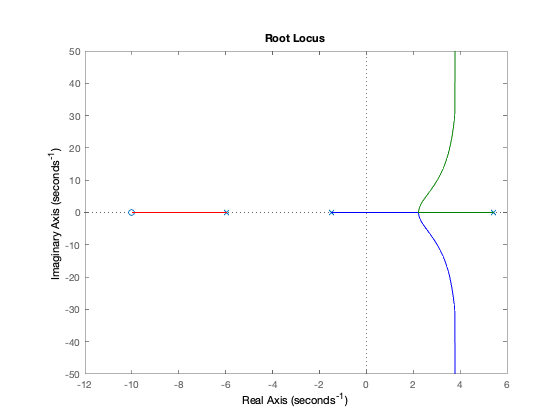

%   add a zero at s=-10 to the compensator
sysCth2 = zpk(-10, 0, 1);

%   loop tf
sysLth2 = minreal(sysCth2*sysPth);

%   root locus
figure;
rlocus(sysLth2);

The zero is located too much inside the LHP, so that its "bending" effect on the two branches in the LHP is not "strong enough". The closed-loop system is still unstable for any choice of the compensator gain.

4)  Move the zero of the compensator of point 3 to the new location $s=-4$. Verify that also in this case, the compensator ( with transfer function $C_\theta(s) = k\,(s+4)/s$ ) is unable to stabilize the closed-loop system, for any choice of the positive gain $k>0$. 

*Solution.*

By adding a zero at $s=-4$ to the compensator, the root locus changes as follows:

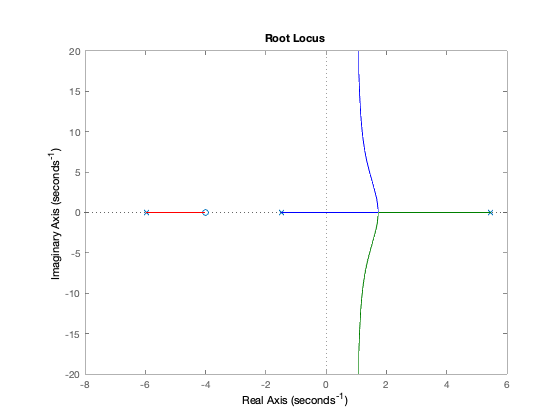

%   add a zero at s=-4 to the compensator
sysCth2 = zpk(-4, 0, 1);

%   loop tf
sysLth2 = minreal(sysCth2*sysPth);

%   root locus
figure;
rlocus(sysLth2);

The effect of the zero is still not strong enough. The closed-loop system remains unstable for any choice of the compensator gain.

5)  Move the zero of the compensator of point 3 to the new location $s=-1$. In this case, verify that for a sufficiently large controller gain $k$, the compensator (with the transfer function $C_\theta(s) = k\,(s+1)/s$) is able to stabilize the closed-loop system.

For example, verify that the choice $k = 11$ produces stable and sufficiently well-damped closed-loop poles. 

*Solution.*

By adding a zero at $s=-1$ to the compensator, the root locus changes as follows:

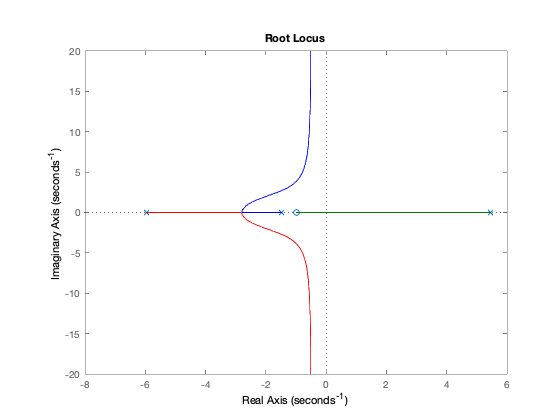

%   add a zero at s=-1 to the compensator
sysCth2 = zpk(-1, 0, 1);

%   loop tf
sysLth2 = minreal(sysCth2*sysPth);

%   root locus
figure;
rlocus(sysLth2);

Now, for a sufficiently high compensator gain, the closed-loop system becomes stable.

It is desired to choose the compensator gain such that the closed-loop poles are stable, and sufficiently well-damped.

From the analysis of the root locus, it can be verified that a reasonable choice for the compensator gain is $k = 11$.

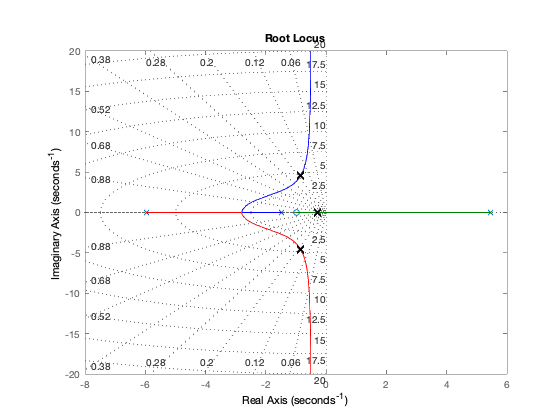

%   adjust compensator gain
sysCth2 = zpk(-1, 0, 11);

%   loop tf
sysLth2 = minreal(sysCth2*sysPth);

%   closed-loop tf
sysTth = feedback(sysLth2, 1);

%   closed-loop poles
p = pole(sysTth);

%   plot poles on root locus
hold on;
plot(p, 'LineStyle', 'none', 'LineWidth', 2.0, ...
    'Marker', 'x', 'MarkerSize', 8.0, 'MarkerEdgeColor', 'k');

%   add s-grid to root locus plot
sgrid;

6)  In order to enlarge the control bandwidth (i.e., speed up the response), it is possible to add an extra zero to the compensator transfer function, so that the root locus branches move further  to the left.

However, adding only a zero to the controller of point 5 yields a not-proper transfer function (i.e. a transfer-function whose numerator has a larger degree than the denominator), which is not physically implementable. To preserve the transfer function properness, it is therefore necessary to add a pole, too.

Consider to add a zero at $s = -3$ and a pole at $s = -10$ to the controller of point 5. The resulting transfer function is:

(5)     $C_\theta(s) \,=\, k\,\frac{(s+3) (s+1)}{s (s+10)}$

Verify that the choice $k = 40$ produces stable and sufficiently well-damped closed--loop poles. Moreover, the complex conjugate closed-loop poles move further to the left into the LHP, which implies that they will also have a larger frequency (i.e. "faster" closed-loop poles).

Note: the transfer function (5) is that of a PID controller with "real" derivative. In fact, in factorized form, the transfer function of the PID compensator with real derivative is equal to: 

(6)         $C_\theta(s) \,=\, K_P\,+\,\frac{K_I}{s} \,+\, \frac{K_D\,s}{T_L\,s\,+\,1} \,=\, [\cdots] \,=\, K_C\,\frac{(s\,+\,z_1)(s\,+\,z_2)}{s\,(s\,+\,p)}$

i.e. it has two zeros, one pole at the origin, and one pole in the open LHP.

*Solution*.

By adding a zero at $s = -3$ and a pole at $s = -10$ to the compensator, the root locus modifies as follows:

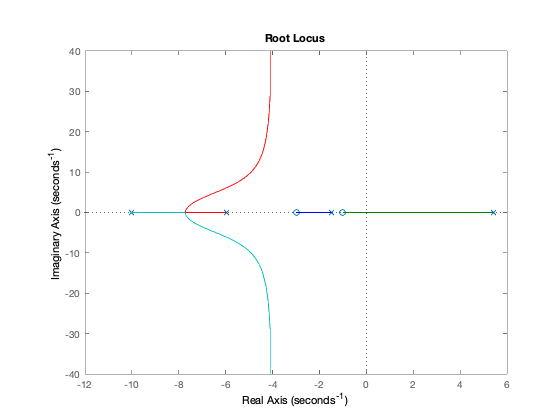

%   add a zero at s=-3 and a pole at s=-10 to the compensator
sysCth3 = zpk([-1, -3], [0, -10], 1);

%   loop tf
sysLth3 = minreal(sysCth3*sysPth);

%   root locus
figure;
rlocus(sysLth3);

A compensator gain equal to $k = 40$ yields sufficiently "fast" and well-damped closed-loop poles:

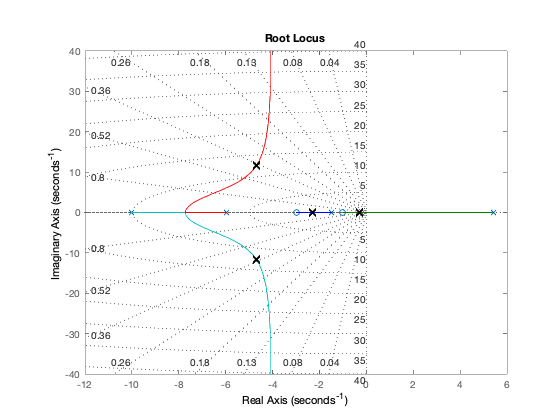

%   adjust compensator gain
sysCth3 = zpk([-1, -3], [0, -10], 40);

%   loop tf
sysLth3 = minreal(sysCth3*sysPth);

%   closed-loop tf
sysTth = feedback(sysLth3, 1);

%   closed-loop poles
p = pole(sysTth);

%   plot poles on root locus
hold on;
plot(p, 'LineStyle', 'none', 'LineWidth', 2.0, ...
    'Marker', 'x', 'MarkerSize', 8.0, 'MarkerEdgeColor', 'k');

%   add s-grid to root locus plot
sgrid;

The resulting balance controller for the inverted pendulum is a PID controller with "real" derivative:

        
$$C_\theta(s) \,=\, K_P\,+\,\frac{K_I}{s} \,+\,
\frac{K_D\,s}{T_L\,s\,+\,1} \,=\;\; [\cdots]\; \;=\,
K_C\,\frac{(s\,+\,z_1)(s\,+\,z_2)}{s\,(s\,+\,p)} 
$$


sysCth = sysCth3


sysCth =
 
  40 (s+1) (s+3)
  --------------
     s (s+10)
 
Continuous-time zero/pole/gain model.



7)  Test the controller of point 6 using the *nonlinear* Simulink model of the cart-pendulum system implemented in point 1 of exercise 1.

As expected, verify that the inverted pendulum is stabilized by the controller designed in point 6, at least for small deviations around the upward vertical equilibrium: for example, evaluate the natural response of the control system to an initial state $\mathbf{x}(0) = [0,\,0,\,\pi/6,\,0]^T$.

However, note that the cart moves indefinitely.

*Solution*.

The balance controller can be tested on simulation, using the nonlinear Simulink model of the cart-pendulum system.

%   open Simulink model
open_system('ex4_sim1.slx');

        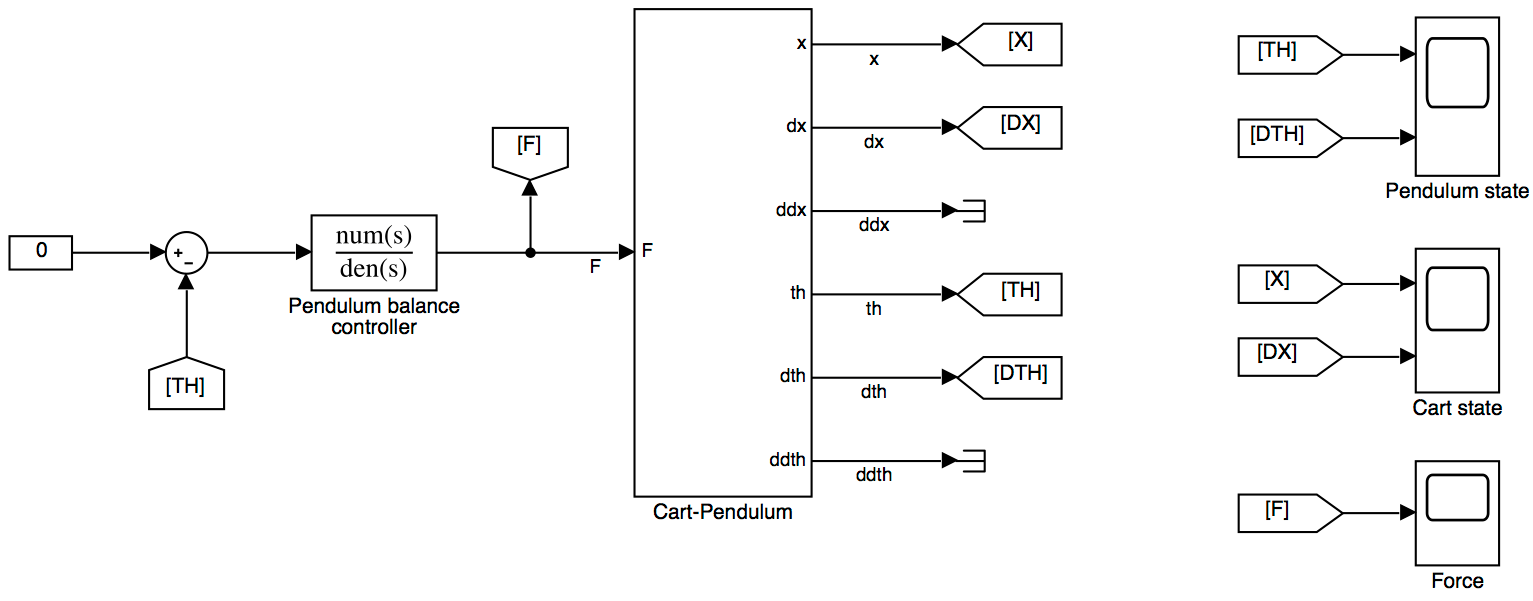

Evaluate the natural response of balance control system designed above for an initial state $\mathbf{x}(0) = [0,\,0,\,\pi/6,\,0]^T$.

%   controller tf num/den
[numCth, denCth] = tfdata(sysCth, 'v');

%   initial state x(0) = [x0, dx0, th0, dth0]^T
x0   = 0;       %   init cart position [m]
dx0  = 0;       %   init cart velocity [m/s]
th0  = pi/6;    %   init pendulum position [rad]
dth0 = 0;       %   init penulum velocity [rad/s]

%   run simulation
sim('ex4_sim1.slx');

Plot the simulation results.

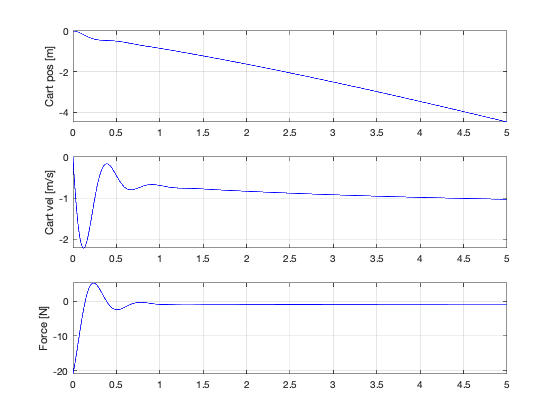

%   extract simulation results
t = cart_state.time;
x = cart_state.signals(1).values;
dx = cart_state.signals(2).values;

th = pend_state.signals(1).values;
dth = pend_state.signals(2).values;

F = force.signals.values;

%   plot simulation results / cart state
figure;
subplot(3, 1, 1);
plot(t, x, 'b');
ylabel('Cart pos [m]') ;
grid on;

subplot(3, 1, 2);
plot(t, dx, 'b');
ylabel('Cart vel [m/s]');
grid on;

subplot(3, 1, 3);
plot(t, F, 'b');
ylabel('Force [N]');
grid on;

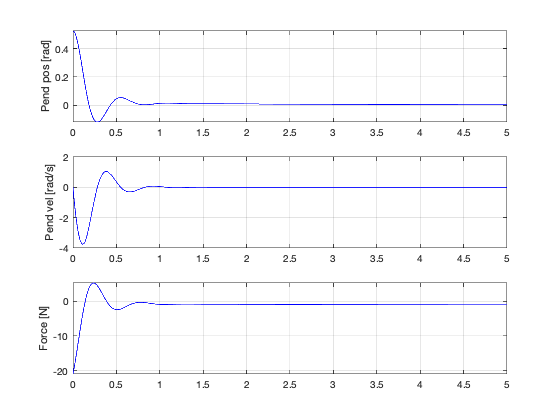


%   plot simulation results / pendulum state
figure;
subplot(3, 1, 1);
plot(t, th, 'b');
ylabel('Pend pos [rad]') ;
grid on;

subplot(3, 1, 2);
plot(t, dth, 'b');
ylabel('Pend vel [rad/s]');
grid on;

subplot(3, 1, 3);
plot(t, F, 'b');
ylabel('Force [N]');
grid on;

As expected, the inverted pendulum is stabilized by the controller $C_\theta(s)$ (at least for small deviations around the upward vertical equilibrium). 

However, the cart moves indefinitely. 

### Design of a combined balance and position controller for the cart-pendulum system

It is desired to control also the position of the cart, by using an additional feedback loop as shown in the block diagram reported below:

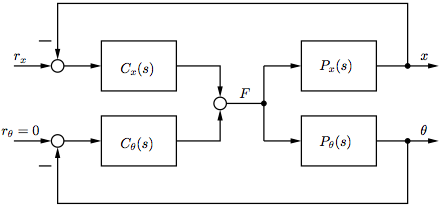

**Figure 3**:  balance and position control system for the cart-pendulum system.

The position controller $C_x(s)$ has to be designed for the closed-loop system with stabilized inverted pendulum. In practice, the plant transfer function to be considered for the design is that from the input force $F$ to the cart position $x$, taking into account the presence of the inverted pendulum balance loop. 

8)  Verify that the transfer function from the input force $F$ to the cart position $x$, taking into account the presence of the inverted pendulum balance loop, is equal to:

(7)     $G_x(s) \,=\, \frac{P_x(s)}{1\,+\,P_\theta(s)\,C_\theta(s)}$

Note that all the poles of $G_x(s)$ are stable, except for a pole at the origin. In principle, the design of the cart position controller $C_x(s)$can be carried out by resorting to conventional frequency response methods (e.g. Bode's method). However, similarly to what done before, the root locus design method is applied next.

*Solution*.

%   balance loop tf
sysLth = minreal(sysCth*sysPth);

%   force to cart position tf (with stabilized inverted pendulum)
sysGx = minreal(sysPx/(1+sysLth));

%   transfer function poles
pole(sysGx)

ans =    0.0000 + 0.0000i
  -4.6945 +11.6171i
  -4.6945 -11.6171i
  -2.2858 + 0.0000i
  -0.2957 + 0.0000i


9)  It is desired to have an integrator in the cart position controller, in order to cope with constant disturbances entering at the plant input (i.e."load" disturbances). Hence, start by considering a position controller of the type $C_x(s) = k/s$.

For any positive controller gain $k>0$, verify that there is always a closed-loop real pole in the open RHP. 

*Solution*.

%   add an integrator to the controller tf
sysCx1 = zpk([], 0, 1);

From the root locus, it can be noticed that for any positive controller gain, there is always a closed-loop real pole in the open RHP.

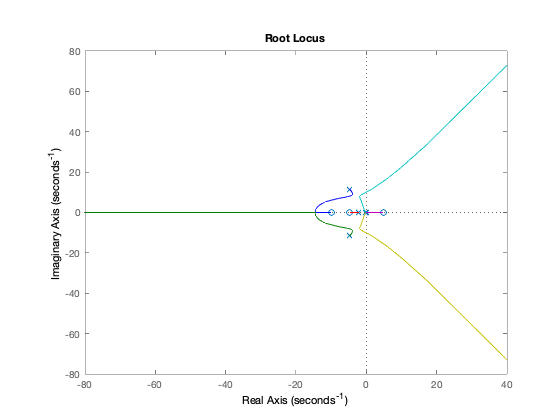

%   loop tf
sysLx1 = minreal(sysCx1*sysGx);

%   root locus
figure;
rlocus(sysLx1);

10)   It is not easy to find a compensation that move the unstable closed-loop real pole of the root locus of point 9 in the open LHP. It can be an idea to check how the shape of the negative root locus is. For this reason, plot the *negative* real locus with the same controller as in point 9.

From an examination of the negative root locus, it can be noticed that with a sufficient number of controller zeros in the open LHP, the root locus can be "bended" toward the open LHP, so that the closed-loop system can be stabilized for a reasonable choice of the controller gain.

*Solution*.

Plot the *negative* root locus with the same controller as in previous point.

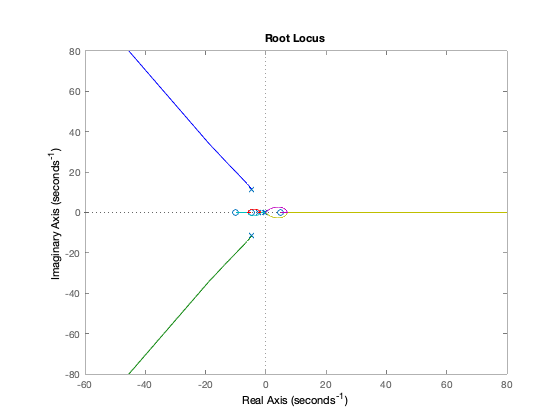

%   change controller sign
sysCx1 = zpk([], 0, -1);

%   loop tf
sysLx1 = minreal(sysCx1*sysGx);

%   root locus
figure;
rlocus(sysLx1);

By adding a sufficient number of LHP poles, it is perhaps possible to bend the small "circle" in the open RHP toward the open LHP.

11) Consider to add a single zero at $s = -0.5$ to the controller of point 10. 

Verify that the resulting controller ( with transfer function $C_x(s) = k(s+0.5)/s$ ) is unable to stabilize the closed-loop system, for any choice of the negative gain $k < 0$ (remember that in point 10 it has been decided to analyze the *negative* root locus).

*Solution*.

Consider to add a zero at $s = -0.5$ to the controller transfer function.

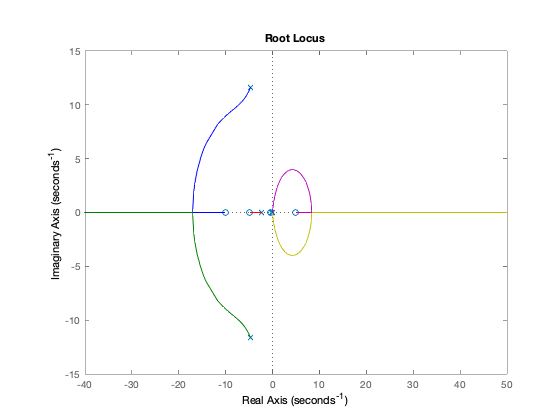

%   add a zero at s=-0.5 to the controller
sysCx2 = zpk(-0.5, 0, -1);

%   loop tf
sysLx2 = minreal(sysCx2*sysGx);

%   root locus
figure;
rlocus(sysLx2);

A single zero is not sufficient to stabilize the closed-loop system.

12)   Consider to add an extra zero at $s = -0.5$ to the controller transfer function of point 11. However, to preserve the transfer function properness, it is also necessary to add a pole. For this reason, consider to add also an extra pole at $s=-10$ to the controller transfer function. The resulting transfer function is:

(8)     $C_x(s) \,=\, k\,\frac{(s+0.5)^2}{s (s+10)}$

Verify that the choice $k = -15$ produces stable and sufficiently well-damped closed-loop poles. Note that the transfer function (8) is again that of a PID controller with "real" derivative.

*Solution*.

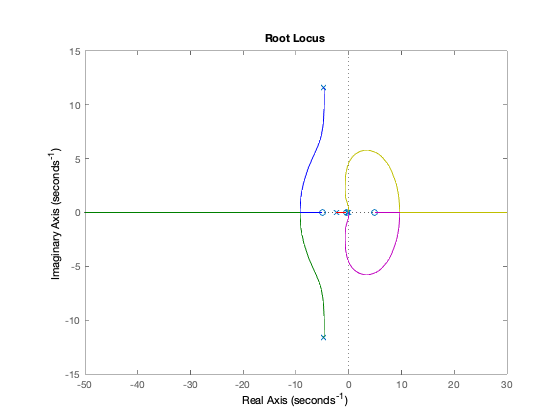

%   add an extra zero at s=-0.5 and a pole at $s=-10$ to the controller
sysCx3 = zpk([-0.5, -0.5], [0, -10], -1);

%   loop tf
sysLx3 = minreal(sysCx3*sysGx);

%   root locus
figure;
rlocus(sysLx3);

The closed-loop system can now be stabilized with a proper choice of the controller gain.

It can be verified that a compensator gain equal to $k = -15$ yields sufficiently well-damped closed-loop poles:

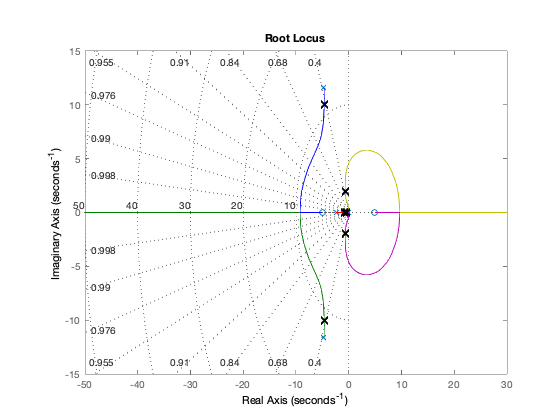

%   adjust controller gain
sysCx3 = zpk([-0.5, -0.5], [0, -10], -15);

%   loop tf
sysLx3 = minreal(sysCx3*sysGx);

%   closed-loop tf
sysTx = feedback(sysLx3, 1);

%   closed-loop poles
p = pole(sysTx);

%   plot poles on root locus
hold on;
plot(p, 'LineStyle', 'none', 'LineWidth', 2.0, ...
    'Marker', 'x', 'MarkerSize', 8.0, 'MarkerEdgeColor', 'k');

%   add s-grid to root locus plot
sgrid;

The resulting position controller for the cart is again a PID controller with "real" derivative:

sysCx = sysCx3


sysCx =
 
  -15 (s+0.5)^2
  -------------
    s (s+10)
 
Continuous-time zero/pole/gain model.



13) Add the controller of point 12 to the Simulink model prepared in point 7, according to the block diagram of Fig. 3. 

Then, verify that the balance+position controller guarantees perfect steady-state tracking of constant cart position set-points, while simultaneously stabilizing the inverted pendulum. For such purpose, simulate the control response with an initial state $\mathbf{x}(0) = [0,\,0,\,\pi/6,\,0]^T$, combined with a cart step position reference of amplitude $A_s=1\,\mathrm{m}$, applied at $t_s = 5\,\mathrm{s}$.

*Solution*.

The position controller can be tested on simulation, using the nonlinear Simulink model of the cart-pendulum system.

%   open Simulink model
open_system('ex4_sim2.slx');

        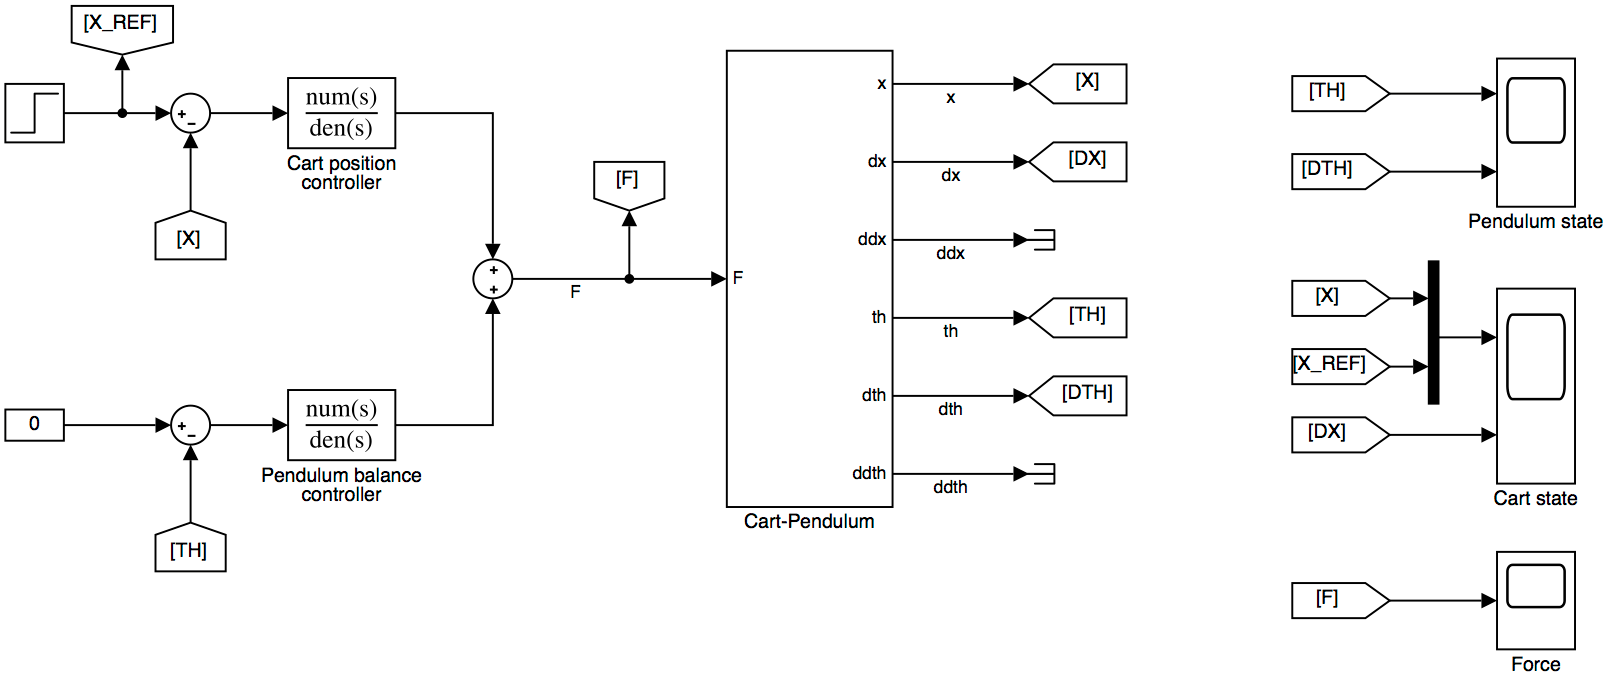

Evaluate the response of balance and position control system designed above, for an initial state $\mathbf{x}(0) = [0,\,0,\,\pi/6,\,0]^T$ and a cart step position reference of amplitude $A_s=1\,\mathrm{m}$, applied at $t_s = 5\,\mathrm{s}$.

%   controller tf num/den
[numCx, denCx] = tfdata(sysCx, 'v');

%   initial state x(0) = [x0, dx0, th0, dth0]^T
x0   = 0;       %   init cart position [m]
dx0  = 0;       %   init cart velocity [m/s]
th0  = pi/6;    %   init pendulum position [rad]
dth0 = 0;       %   init penulum velocity [rad/s]

%   cart step position ref
As = 1;         %   amplitude [m]
ts = 5;         %   time [s]

%   run simulation
sim('ex4_sim2.slx');

Plot the simulation results.

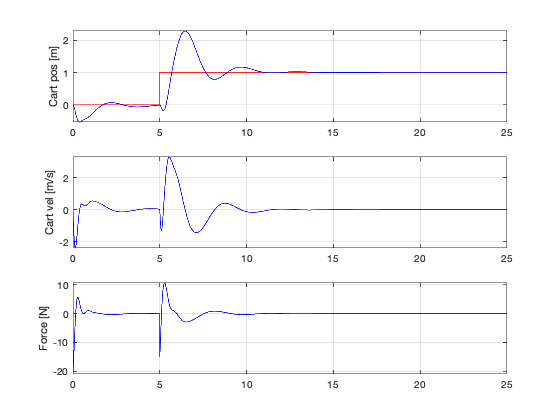

%   extract simulation results
t = cart_state.time;
x = cart_state.signals(1).values(:,1);
x_ref = cart_state.signals(1).values(:,2);
dx = cart_state.signals(2).values;

th = pend_state.signals(1).values;
dth = pend_state.signals(2).values;

F = force.signals.values;

%   plot simulation results / cart state
figure;
subplot(3, 1, 1);
plot(t, x_ref, 'r');
hold on
plot(t, x, 'b');
ylabel('Cart pos [m]') ;
grid on;

subplot(3, 1, 2);
plot(t, dx, 'b');
ylabel('Cart vel [m/s]');
grid on;

subplot(3, 1, 3);
plot(t, F, 'b');
ylabel('Force [N]');
grid on;

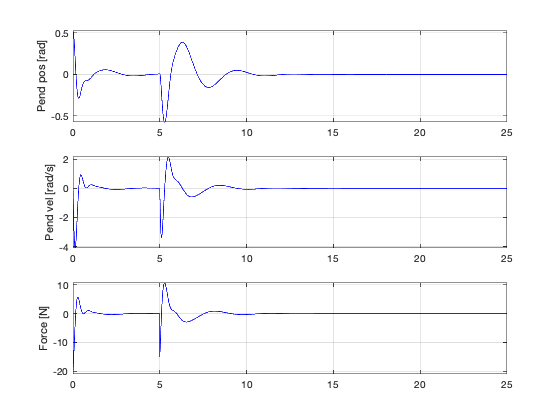


%   plot simulation results / pendulum state
figure;
subplot(3, 1, 1);
plot(t, th, 'b');
ylabel('Pend pos [rad]') ;
grid on;

subplot(3, 1, 2);
plot(t, dth, 'b');
ylabel('Pend vel [rad/s]');
grid on;

subplot(3, 1, 3);
plot(t, F, 'b');
ylabel('Force [N]');
grid on;

14)  Thanks to the integral action, the cart position controller of point 12 is capable to compensate for constant force disturbances entering at the plant input (*load disturbances*). Verify such capability by repeating the simulation of point 13 with an extra step force disturbance of amplitude $A_d = 5\,\mathrm{N}$, applied at $t_d = 15\,\mathrm{s}$.

*Solution*.

%   open Simulink model
open_system('ex4_sim3.slx');

        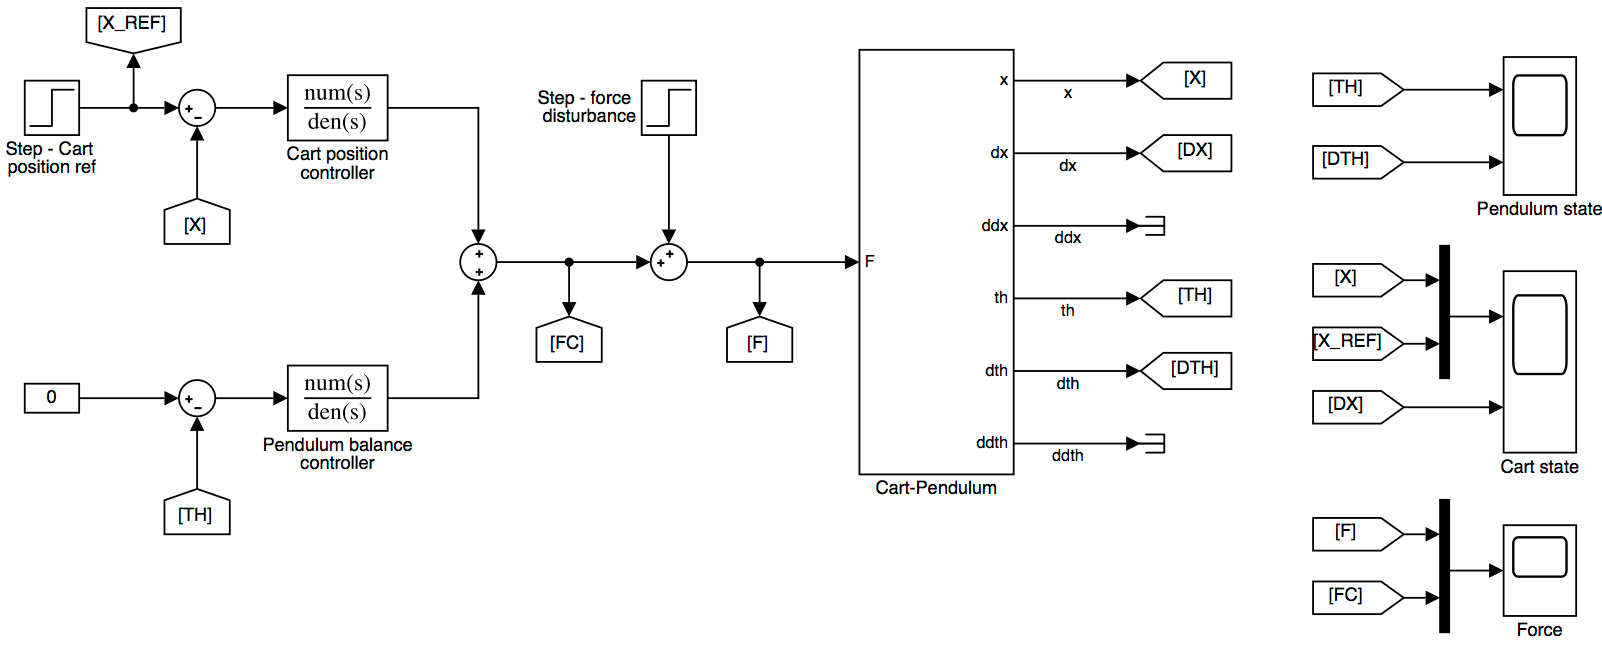

Run the simulation.

%   cart step force disturbance
Ad = 5;         %   amplitude [m]
td = 15;        %   time [s]

%   run simulation
sim('ex4_sim3.slx');

Plot the simulation results.

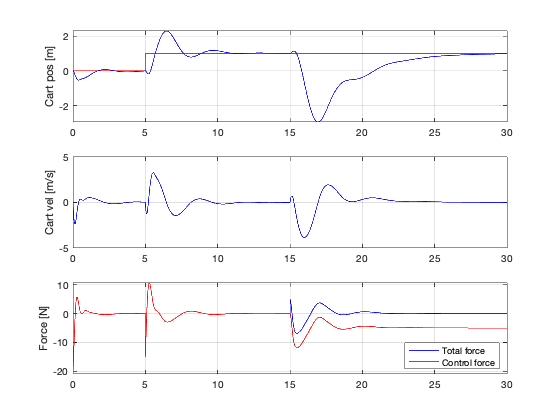

%   extract simulation results
t = cart_state.time;
x = cart_state.signals(1).values(:,1);
x_ref = cart_state.signals(1).values(:,2);
dx = cart_state.signals(2).values;

th = pend_state.signals(1).values;
dth = pend_state.signals(2).values;

F = force.signals.values(:,1);
Fc = force.signals.values(:,2);

%   plot simulation results / cart state
figure;
subplot(3, 1, 1);
plot(t, x_ref, 'r');
hold on
plot(t, x, 'b');
ylabel('Cart pos [m]') ;
grid on;

subplot(3, 1, 2);
plot(t, dx, 'b');
ylabel('Cart vel [m/s]');
grid on;

subplot(3, 1, 3);
plot(t, F, 'b');
hold on;
plot(t, Fc, 'r');
ylabel('Force [N]');
grid on;
hl = legend('Total force', 'Control force');
set(hl, 'Location', 'SouthEast');

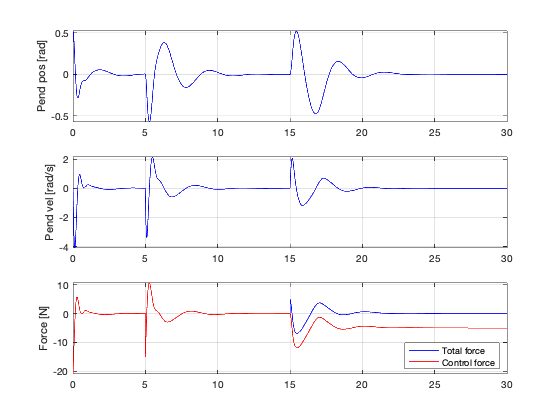


%   plot simulation results / pendulum state
figure;
subplot(3, 1, 1);
plot(t, th, 'b');
ylabel('Pend pos [rad]') ;
grid on;

subplot(3, 1, 2);
plot(t, dth, 'b');
ylabel('Pend vel [rad/s]');
grid on;

subplot(3, 1, 3);
plot(t, F, 'b');
hold on;
plot(t, Fc, 'r');
ylabel('Force [N]');
grid on;
hl = legend('Total force', 'Control force');
set(hl, 'Location', 'SouthEast');